Km = 0.3249

Km = 0.3249

Ke = 0.3249

Ke = 0.3249

J = 0.0016

J = 0.0016

R = 4.6808

R = 4.6808

L = 1.0411

L = 1.0411

W = tf(Km/J/R, [1 Ke*Km/J/R 0])

W =
 
      43.38
  -------------
  s^2 + 14.09 s
 
Continuous-time transfer function.



syms w s t
% b = Km/J/R
% a = Ke*Km/J/R
% teta = 1/Km - 1/Km*exp(-Km*Ke/J/R*t)
% pereh = t/Km+J*R/Km^2/Ke*exp(-Km*Ke/J/R*t)
% step(W)
% hold on
% grid on
% p = [1 Km*Ke/J/R 0]
% roots(p)
% fplot(pereh,[0,35],"red")

% achx
afc = (w*Km/J/R) / (sqrt( (Km*Ke/J/R )^2+w^2))

$$afc = \frac{2030625\,w}{46808\,\sqrt{w^{2}+\frac{3494930300964891}{17592186044416}}}$$

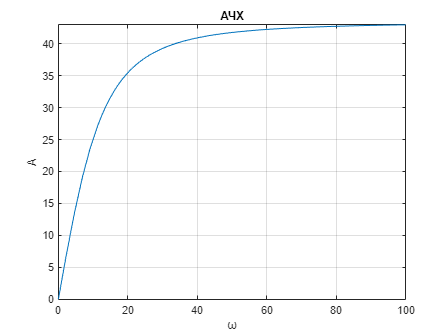

fplot(afc,[0,100])
grid on
title("АЧХ")
xlabel("ω")
ylabel("A")


% фчх
pfc= atan(w/0) + atan(-w/( Km*Ke/J/R ))

$$pfc = \mathrm{atan}\left(w\,\infty \right)-\mathrm{atan}\left(\frac{281474976710656\,w}{3967337495236741}\right)$$

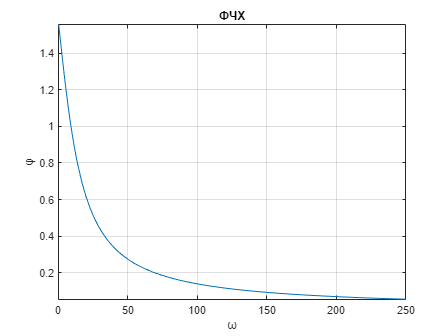

fplot(pfc,[0,250])

title("ФЧХ")
xlabel("ω")
ylabel("φ")
grid on

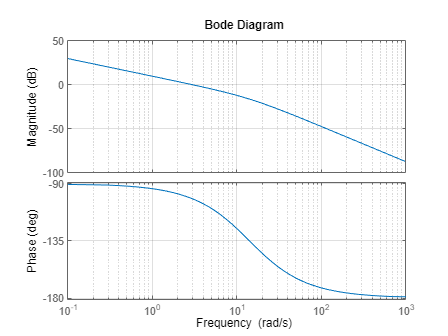

% step(W)
% impulse(W)
bode(W)
grid on